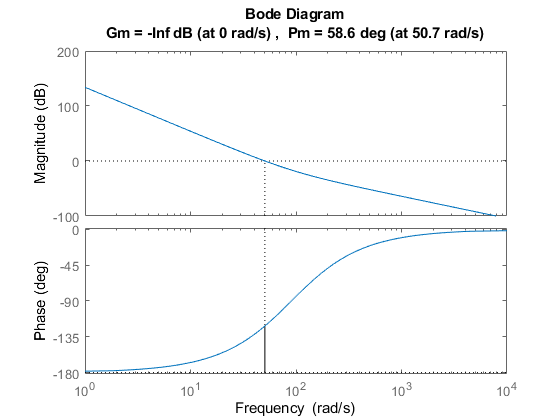

mech.L = 0.5;
mech.l = 0.1;
mech.h = 0.5;
mech.H = 0.3;
mech.L = 1;
mech.hp = 0.2;

% physics constants
const.g = 9.81;
const.rad2deg = 180/pi;

% H bridge
driver.kc = 1;
driver.Tc = 2e-6;

% DC stepper motor
stepper.La = 1.6e-3;
stepper.Ra = 2.5;
stepper.Km = 7.68e-3;
stepper.tausf = 0;
stepper.Jeq = 5.5e-9;
stepper.Beq = 2.5e-9;
stepper.Nr = 100;
stepper.p = 2;
stepper.pp = stepper.Nr/stepper.p;
stepper.precision = 360/(stepper.p*stepper.Nr);
stepper.precision2 = stepper.precision/2;

% arduino
arduino.arch = 8;
arduino.vcc = 5;
arduino.gnd = 0;
arduino.adc.n_bits = 10;
arduino.adc.q_step = (arduino.vcc - arduino.gnd)/(2^(arduino.adc.n_bits));
arduino.adc.Tc = 0.001;

% acs712 hall-effect current sensor
sensor.current.max_a = 5;
sensor.current.q_step = sensor.current.max_a/((arduino.vcc - arduino.gnd)/2);

% potentiometer
sensor.pot.deg2V = 

% requests
request.Mp = 0.1;
request.ts = 0.1;
request.alpha = 4;

s = tf('s');
T = -const.g*mech.l/mech.L*1/(s*s);
M = 1/s;
P = M*T;

[request.wc, request.phm] = getWgcPhim(request.Mp, request.ts);
request.fc = request.wc/2/pi;
[pid.Kp, pid.Ki, pid.Kd] = getPIDBodeFreq(P, request.fc, request.phm, request.alpha);
pid.T_l = 1/(10*request.wc);
pid.Kw  = 5/request.ts;

C = pid.Kp + pid.Ki/s + pid.Kd*s;
margin(C*P)

%% Definition of Bode Method
% set of utility routines

function [wgc, phim] = getWgcPhim(Mp, ts)
    delta = log(1/Mp)/sqrt(pi^2+log(1/Mp)^2);
    wgc = 3/delta/ts;
    phim = 180/pi*atan(2*delta/sqrt(sqrt(1+4*delta^4)-2*delta^2)); % Phase margin [deg]
end

function [Kp,Ki,Kd] = getPIDBodeFreq(plant, freq, phim, alpha)
    wgc = 2*pi*freq;
    [Kp,Ki,Kd] = getPIDBode(plant, wgc, phim, alpha);
end

function [Kp,Ki,Kd] = getPIDBode(plant, wgc, phim, alpha)
    [mag, phase] = bode(plant, wgc);
    DeltaK = 1 / mag;
    DeltaPhi = -180 + phim - phase;
    tmp = tand(DeltaPhi);
    Td = (tmp + sqrt(tmp^2 + 4/alpha))/(2*wgc);
    Ti = alpha * Td;
    Kp = DeltaK * cosd(DeltaPhi);
    Ki = Kp / Ti;
    Kd = Kp * Td;
    s = tf('s');
    C = Kp + Ki * 1/s + Kd * s;
    %[a,b,c,d] = margin(C*plant);
    %delta_wgc = c - wgc;
    %delta_phim = d - phim;
    %assert(delta_wgc < 0.01, "failed to build PID");
    %assert(delta_phim < 0.01, "failed to build PID");
end